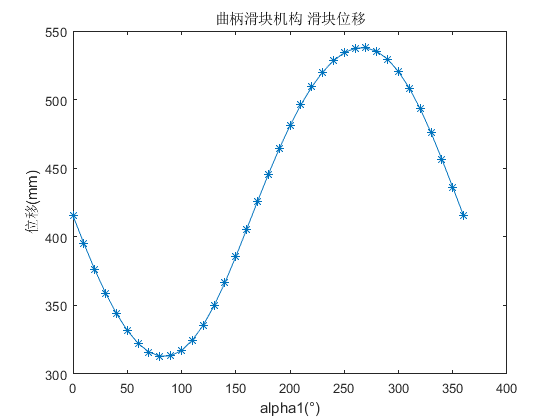


% 定义杆长、间距、角速度等初始物理量
l1 = 100;  % 曲柄长度 mm
l2 = 350; l3 = 350; l4 = 500;
m = 300; % 支座A、C水平距离
S0 = 400; % 支座A、C竖直距离





% 定义各杆角度、角速度，角加速度
%杆AB
alpha1= 0:10:360; % 自变量 时间 s
omega1=5; % 曲柄角速度 rad/s
acceleration1=0; % 曲柄匀角速度旋转
n = length(alpha1); % 自变量个数

%定义滑块位移、速度、加速度
ySlide = zeros(1,n); % 滑块的位移
velocitySlide = zeros(1,n); % 滑块的速度 mm/s
accelerationSlide = zeros(1,n); % 滑块速度 mm/s

for iterTime = 1:n
% 杆BD
syms alpha2 ;
syms omega2;
syms acceleration2;

% 杆CD
syms alpha3 ;
syms omega3;
syms acceleration3;

% 杆DE
syms alpha4 ;
syms omega4;
syms acceleration4;



%杆的位移方程
% 矢量方程(a)：l4+l3=S;
% 矢量方程(b): m+l1+l2+l3=S0
    
syms S;

% 矢量方程的投影
% 方程(a)
% 沿x轴
q1 = l4*cosd(alpha4)+l3*cosd(alpha3);
% % 沿y轴
q2 = l4*sind(alpha4)+l3*sind(alpha3)-S;
%方程(b)
% 沿x轴
q3 = m+l1*cosd(alpha1(iterTime))+l2*cosd(alpha2)+l3*cosd(alpha3);
% 沿y轴
q4 = l1*sind(alpha1(iterTime))+l2*sind(alpha2)+l3*sind(alpha3)-S0;

%求解位移方程，得出 alpha2、alpha3、alpha4、S
%采用迭代计算的方法，用前一时刻的位移来确定后一时刻的位移
if iterTime == 1
   x0 = [415 99 171 46];
end

   T = vpasolve (q1,q2,q3,q4,x0);
   alpha2 = T.alpha2;
   alpha3 = T.alpha3;

   alpha4 = T.alpha4;
    ySlide(iterTime) = T.S;
   if iterTime > 1
   x0 = [ySlide((iterTime-1)) alpha2 alpha3 alpha4];
   end
   
   
   
%杆的位移方程对时间求一阶导
syms V;
% 沿x轴
q5 = -l4*sind(alpha4)*omega4-l3*sind(alpha3)*omega3;
% 沿y轴
q6 = l4*cosd(alpha4)*omega4+l3*cosd(alpha3)*omega3-V;
%方程(b)
% 沿x轴
q7 = (-1)*l1*sind(alpha1(iterTime))*omega1-l2*sind(alpha2)*omega2-l3*sind(alpha3)*omega3;
% 沿y轴
q8 = l1*cosd(alpha1(iterTime))*omega1+l2*cosd(alpha2)*omega2+l3*cosd(alpha3)*omega3;
%求解速度方程，得出 omega2、omega3、omega4、velocitySlide
P = vpasolve (q5,q6,q7,q8);
velocitySlide(iterTime) = double(P.V);
omega2 = P.omega2;
omega3 = P.omega3;
omega4 = P.omega4;




%杆的位移方程对时间求二阶导
syms B;
%方程(a)
% 沿x轴
q9 = -l4*cosd(alpha4)*(omega4)^2-l4*sind(alpha4)*acceleration4-l3*cosd(alpha3)*(omega3)^2-l3*sind(alpha3)*acceleration3;
% 沿y轴
q10 = -l4*sind(alpha4)*(omega4)^2+l4*cosd(alpha4)*acceleration4-l3*sind(alpha3)*(omega3)^2+l3*cosd(alpha3)*acceleration3-B;
%方程(b)
% 沿x轴
q11 = (-1)*l1*cosd(alpha1(iterTime))*(omega1)^2-l1*sind(alpha1(iterTime))*acceleration1-l2*cosd(alpha2)*(omega2)^2-l2*sind(alpha2)*acceleration2-l3*cosd(alpha3)*(omega3)^2-l3*sind(alpha3)*acceleration3;
% 沿y轴
q12 = (-1)*l1*sind(alpha1(iterTime))*(omega1)^2+l1*cosd(alpha1(iterTime))*acceleration1-l2*sind(alpha2)*(omega2)^2+l2*cosd(alpha2)*acceleration2-l3*sind(alpha3)*(omega3)^2+l3*cosd(alpha3)*acceleration3;
%求解加速度方程，得出 acceleration2,acceleration3,acceleration4,accelerationSlide
Q = vpasolve (q9,q10,q11,q12);
accelerationSlide(iterTime) = Q.B;

clearvars  alpha2 alpha3 alpha4 S omega2 omega3 omega4 V acceleration2 acceleration3 acceleration4 B T P Q;
   end
figure(1)
plot(alpha1, ySlide,'-*');
title('曲柄滑块机构 滑块位移');
xlabel('alpha1(°)');
ylabel('位移(mm)');

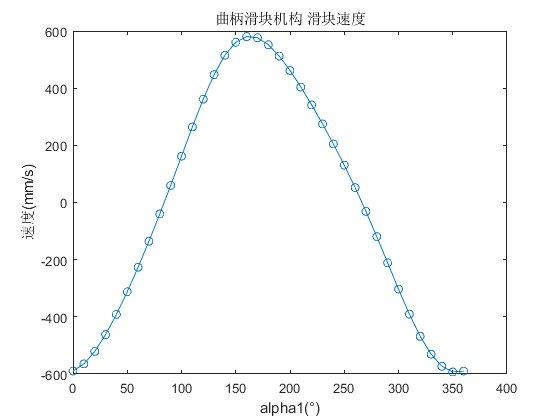



figure(2)
plot(alpha1, velocitySlide,'-o');
title('曲柄滑块机构 滑块速度');
xlabel('alpha1(°)');
ylabel('速度(mm/s)');

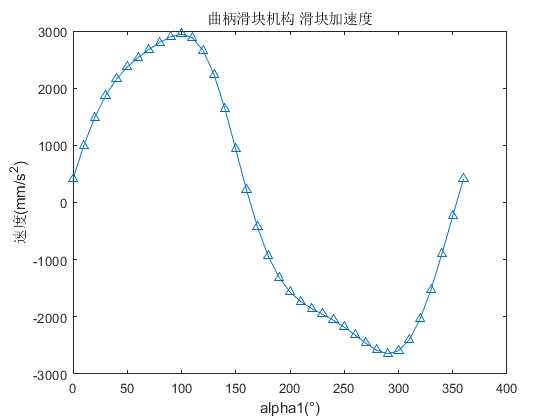


figure(3)
plot(alpha1, accelerationSlide,'-^');
title('曲柄滑块机构 滑块加速度');
xlabel('alpha1(°)');
ylabel('速度(mm/s^2)');